# Heartbeat Monitoring

## Heartbeat Simulation

clear all;
clc;
close all;

disp('Heartbeat Simulation...');

Heartbeat Simulation...



jsonText = fileread('1.json');
data = jsondecode(jsonText);
fsr_signal = double(data.data_PPG);  
fs = 1000;                            % Sampling rate

signal = fsr_signal(1:60*fs);

disp('Data loaded.');

Data loaded.


disp('Simulation starting');

Simulation starting



figure('Position',[150 100 1100 650]);

% Three plots
subplot(3,1,1);
h1 = plot(zeros(1,5000),'b','LineWidth',1.3);
title('Raw FSR Sensor Signal');
ylabel('Amplitude');
grid on;

subplot(3,1,2);
h2 = plot(zeros(1,5000),'g','LineWidth',1.3);
title('Cleaned Signal');
ylabel('Amplitude');
grid on;

subplot(3,1,3);
h3 = plot(0,0,'r','LineWidth',1.5);
title('Heart Rate (BPM)');
ylabel('BPM');
xlabel('Time (seconds)');
grid on;
yline(60,'r--','Bradycardia');
yline(100,'r--','Tachycardia');

sgtitle('Heartbeat Simulation');

% Simulation
disp('Simulation is running...');

Simulation is running...


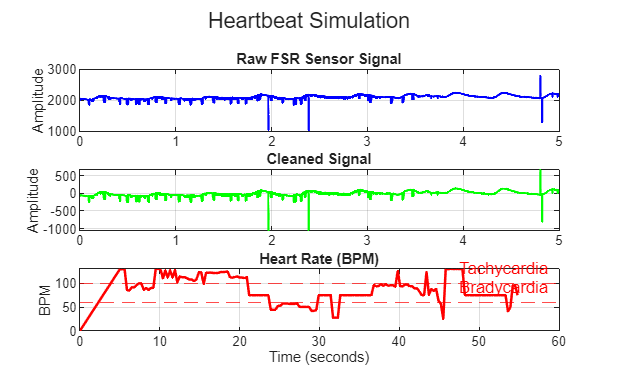


for start = 5000:300:length(signal)-5000
    
    chunk = signal(start:start+5000-1);
    time = (0:4999)/fs;
 
    clean_chunk = chunk - mean(chunk);
 
    [~, peaks] = findpeaks(clean_chunk, 'MinPeakDistance', 450, 'MinPeakHeight', 0.6*max(clean_chunk));
    
    % Calculate heart rate
    if length(peaks) >= 3
        hr = 60 / mean(diff(peaks)/fs);
    else
        hr = 75;   % default value
    end
    
    % Update plots
    set(h1, 'XData', time, 'YData', chunk);
    set(h2, 'XData', time, 'YData', clean_chunk);
    set(h3, 'XData', [get(h3,'XData') start/fs], 'YData', [get(h3,'YData') hr]);
    
    drawnow;
    pause(0.1);   
end


disp('Simulation Finished!');

Simulation Finished!


## Confusion Matrix

%% ===================== MACHINE LEARNING CLASSIFICATION =====================

disp('=== Machine Learning Classification ===');

=== Machine Learning Classification ===



hr_values = get(h3, 'YData');

meanHR = movmean(hr_values, 8);
hr_variation = movstd(hr_values, 8);

features = table(meanHR', hr_variation', 'VariableNames', {'MeanHR', 'HRVariation'});

labels = categorical(strings(length(hr_values),1));
for i = 1:length(hr_values)
    if hr_values(i) < 60
        labels(i) = 'Bradycardia';
    elseif hr_values(i) > 100
        labels(i) = 'Tachycardia';
    else
        labels(i) = 'Normal';
    end
end

model = fitctree(features, labels);
predicted = predict(model, features);

accuracy = sum(predicted == labels) / length(labels) * 100;

% Final Results
final_avg_hr = mean(hr_values(end-30:end));
final_prediction = mode(predicted(end-30:end));

disp('--- Machine Learning Result ---');

--- Machine Learning Result ---


disp(['Average Heart Rate: ', num2str(final_avg_hr), ' BPM']);

Average Heart Rate: 88.6654 BPM


disp(['Heart Rate Variation: ', num2str(mean(hr_variation(end-30:end))), ' BPM']);

Heart Rate Variation: 15.8554 BPM


disp(['ML Predicted Condition: ', char(final_prediction)]);

ML Predicted Condition: Normal


disp(['Model Accuracy: ', num2str(accuracy), '%']);

Model Accuracy: 92.8571%


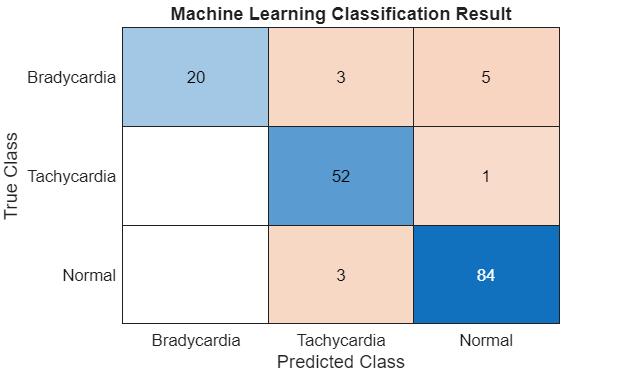


% Confusion matrix
figure;
confusionchart(labels, predicted);
title('Machine Learning Classification Result');


disp(' ');

disp('In the Confusion Matrix:');

In the Confusion Matrix:


disp('→ Darker blue colour = More correct predictions');

→ Darker blue colour = More correct predictions


disp('→ Lighter colour = Fewer or wrong predictions');

→ Lighter colour = Fewer or wrong predictions



disp('Machine Learning Finished!');

Machine Learning Finished!


## Bradycardia and Tachycardia dataset

clear all;
clc;

fs = 1000;
duration = 60;
t = (0:1/fs:duration-1/fs)';

% Normal (~78 BPM)
normal_signal = zeros(length(t),1);
for i = 1:round(fs*60/78):length(t)
    if i+45 <= length(t)
        normal_signal(i:i+45) = 1.8 * sin(linspace(0, 2*pi, 46)).^2;
    end
end
normal_signal = normal_signal + 0.12*randn(size(normal_signal));

% Bradycardia ~33 BPM
brady_signal = zeros(length(t),1);
for i = 1:round(fs*60/33):length(t)
    if i+75 <= length(t)
        brady_signal(i:i+75) = 2.5 * sin(linspace(0, 2*pi, 76)).^2;
    end
end
brady_signal = brady_signal + 0.16*randn(size(brady_signal));

% Tachycardia ~170 BPM
tachy_signal = zeros(length(t),1);
for i = 1:round(fs*60/170):length(t)
    if i+28 <= length(t)
        tachy_signal(i:i+28) = 1.55 * sin(linspace(0, 2*pi, 29)).^2;
    end
end
tachy_signal = tachy_signal + 0.12*randn(size(tachy_signal));

% Save as json file 
writestruct(struct('UID','subject_normal','age',25,'weight',65,'height',175,'data_PPG',normal_signal), '1.json');
writestruct(struct('UID','subject_brady','age',25,'weight',65,'height',175,'data_PPG',brady_signal), 'bradycardia_data.json');
writestruct(struct('UID','subject_tachy','age',25,'weight',65,'height',175,'data_PPG',tachy_signal), 'tachycardia_data.json');

disp('Datasets created successfully');

Datasets created successfully


disp(' -> Bradycardia ~33 BPM');

 -> Bradycardia ~33 BPM


disp(' -> Tachycardia ~170 BPM');

 -> Tachycardia ~170 BPM


## Comparison

%% Load datasets
normal = jsondecode(fileread('1.json'));
brady  = jsondecode(fileread('bradycardia_data.json'));
tachy  = jsondecode(fileread('tachycardia_data.json'));
sigN = double(normal.data_PPG);
sigB = double(brady.data_PPG);
sigT = double(tachy.data_PPG);
fs = 1000;

%% ── Robust HR + signal feature extraction ──────────────────────────────────
function stats = extract_features(sig, fs, label)
    % Normalize
    sig = sig - mean(sig);
    thresh = 0.5 * max(sig);

    [pks, locs] = findpeaks(sig, 'MinPeakDistance', round(fs*0.35), ...
                                 'MinPeakHeight',   thresh);
    ibi      = diff(locs) / fs;          % inter-beat intervals (seconds)
    hr_beats = 60 ./ ibi;                % BPM per beat

    stats.Label    = label;
    stats.MeanBPM  = mean(hr_beats);
    stats.StdBPM   = std(hr_beats);
    stats.MinBPM   = min(hr_beats);
    stats.MaxBPM   = max(hr_beats);
    stats.MeanAmp  = mean(pks);          % average peak amplitude
    stats.NoiseRMS = rms(sig - ...       % residual noise after removing peaks
                    smooth(sig, round(fs*0.1)));
    stats.NumBeats = length(pks);
end

sN = extract_features(sigN, fs, 'Normal');
sB = extract_features(sigB, fs, 'Bradycardia');
sT = extract_features(sigT, fs, 'Tachycardia');

%% ── 1. Enhanced Comparison Table ───────────────────────────────────────────
T = table( ...
    ["Normal"; "Bradycardia"; "Tachycardia"], ...
    [sN.MeanBPM; sB.MeanBPM; sT.MeanBPM], ...
    [sN.StdBPM;  sB.StdBPM;  sT.StdBPM], ...
    [sN.MinBPM;  sB.MinBPM;  sT.MinBPM], ...
    [sN.MaxBPM;  sB.MaxBPM;  sT.MaxBPM], ...
    [sN.MeanAmp; sB.MeanAmp; sT.MeanAmp], ...
    [sN.NumBeats; sB.NumBeats; sT.NumBeats], ...
    'VariableNames', {'Condition','Mean_BPM','Std_BPM','Min_BPM','Max_BPM','Avg_Amplitude','Num_Beats'});

disp('===== COMPREHENSIVE SIGNAL COMPARISON TABLE =====');

===== COMPREHENSIVE SIGNAL COMPARISON TABLE =====


disp(T);

      Condition      Mean_BPM    Std_BPM    Min_BPM    Max_BPM    Avg_Amplitude    Num_Beats
    _____________    ________    _______    _______    _______    _____________    _________

    "Normal"          78.061      1.7004    75.567     80.754         1.899            78   
    "Bradycardia"     33.008     0.41634     32.31     33.746        2.6531            33   
    "Tachycardia"      153.7      31.784     86.58     170.94        1.5853           144   



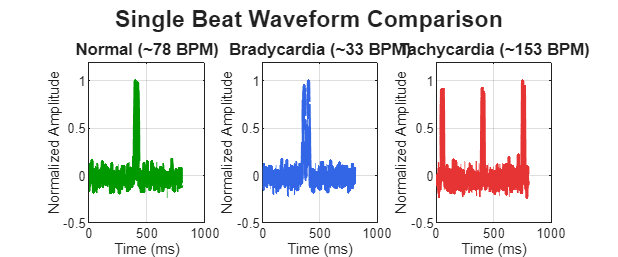


%% ── 2. Waveform Comparison (separate subplots, 1 clean beat each) ───────────
figure('Position', [100 100 1200 500]);
sgtitle('Single Beat Waveform Comparison', 'FontSize', 14, 'FontWeight', 'bold');

signals = {sigN, sigB, sigT};
names   = {'Normal (~78 BPM)', 'Bradycardia (~33 BPM)', 'Tachycardia (~153 BPM)'};
colors  = {[0 0.6 0], [0.2 0.4 0.9], [0.9 0.2 0.2]};

for k = 1:3
    sig = signals{k};
    sig = sig - mean(sig);
    thresh = 0.5 * max(sig);

    [~, locs] = findpeaks(sig, 'MinPeakDistance', round(fs*0.35), ...
                               'MinPeakHeight', thresh);

    subplot(1, 3, k);
    if length(locs) >= 3
        % Extract window: half beat before to half beat after peak
        pk = locs(3);
        half = round(fs * 0.4);
        idx = max(1, pk-half) : min(length(sig), pk+half);
        t_ms = (0:length(idx)-1) / fs * 1000;
        win = sig(idx) / max(abs(sig(idx)));  % normalize
        plot(t_ms, win, 'Color', colors{k}, 'LineWidth', 2);
    end
    title(names{k}, 'FontSize', 10);
    xlabel('Time (ms)');
    ylabel('Normalized Amplitude');
    ylim([-0.5 1.2]);
    grid on;
end

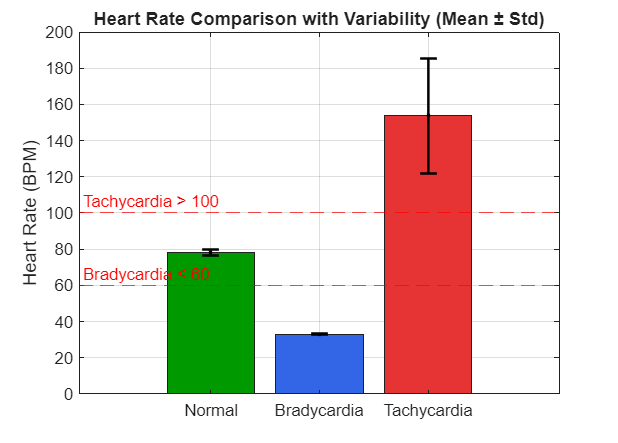


%% ── 3. BPM Bar Chart with Error Bars & Reference Zones ─────────────────────
figure('Position',[100 100 700 500]);
means = [sN.MeanBPM, sB.MeanBPM, sT.MeanBPM];
stds  = [sN.StdBPM,  sB.StdBPM,  sT.StdBPM];
b = bar(means, 'FaceColor', 'flat');
b.CData = [0 0.6 0; 0.2 0.4 0.9; 0.9 0.2 0.2];  % green, blue, red
hold on;
errorbar(1:3, means, stds, 'k.', 'LineWidth', 1.5, 'CapSize', 10);

% Reference lines
yline(60,  'r--', 'Bradycardia < 60', 'LabelHorizontalAlignment','left');
yline(100, 'r--', 'Tachycardia > 100','LabelHorizontalAlignment','left');

set(gca, 'XTickLabel', {'Normal','Bradycardia','Tachycardia'});
ylabel('Heart Rate (BPM)');
title('Heart Rate Comparison with Variability (Mean ± Std)');
grid on;

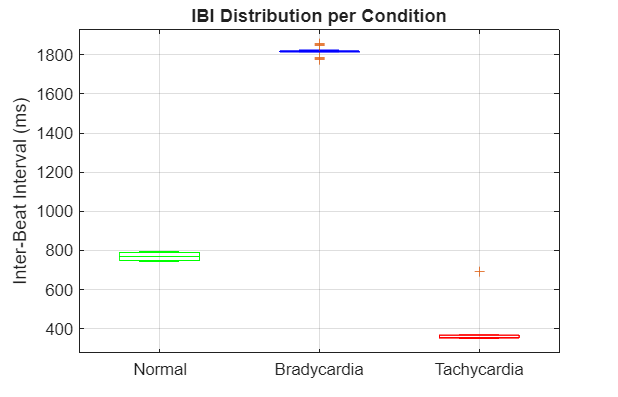


%% ── 4. IBI Distribution (box plot) ─────────────────────────────────────────
figure('Position',[100 100 700 450]);

function ibi = get_ibi(sig, fs)
    sig = sig - mean(sig);
    [~, locs] = findpeaks(sig, 'MinPeakDistance', round(fs*0.35), ...
                               'MinPeakHeight', 0.5*max(sig));
    ibi = diff(locs) / fs * 1000;  % in ms
end

ibiN = get_ibi(sigN, fs);
ibiB = get_ibi(sigB, fs);
ibiT = get_ibi(sigT, fs);

maxLen = max([length(ibiN), length(ibiB), length(ibiT)]);
ibiMat = NaN(maxLen, 3);
ibiMat(1:length(ibiN),1) = ibiN;
ibiMat(1:length(ibiB),2) = ibiB;
ibiMat(1:length(ibiT),3) = ibiT;

boxplot(ibiMat, 'Labels', {'Normal','Bradycardia','Tachycardia'}, ...
        'Colors', 'gbr', 'Width', 0.5);
ylabel('Inter-Beat Interval (ms)');
title('IBI Distribution per Condition');
grid on;


%% ── 5. Pairwise Difference Summary ─────────────────────────────────────────
disp('===== PAIRWISE BPM DIFFERENCE =====');

===== PAIRWISE BPM DIFFERENCE =====


pairs = {'Normal vs Bradycardia', 'Normal vs Tachycardia', 'Brady vs Tachy'};
diffs = abs([sN.MeanBPM-sB.MeanBPM, sN.MeanBPM-sT.MeanBPM, sB.MeanBPM-sT.MeanBPM]);
for i = 1:3
    fprintf('%s : %.1f BPM difference\n', pairs{i}, diffs(i));
end

Normal vs Bradycardia : 45.1 BPM difference
Normal vs Tachycardia : 75.6 BPM difference
Brady vs Tachy : 120.7 BPM difference
